clc
clear
load("DataAndVariables\BaseDefinitions.mat");
load("DataAndVariables\AvgValues.mat");
addpath("Functions\");

measuremedOutputs = [Psch(2:end,:) ; Qsch(2:end,:)];
p = 3;
n = 14;
m = n;

Hp = 4;
Hu = 4;
Q = 10*eye(n);
R = eye(p);

rho = 100; % slack weight

Ts = 10; %How long does a simulation step take [s]
NoSamples = 96; % 96 = all samples
interval = 15; % 15 minutes between data
simTime = NoSamples*((interval * 60) / Ts);
t = linspace(0,45,simTime);

## Linear model

k = 1; % 71

% initial values
[Vout, Sout, Sensitivity, J] = NewRapV2(measuremedOutputs(:,k));

A = eye(nrBus-1);
B = Sensitivity(:,[1 7 10]);

## MPC

du = zeros(p,simTime);
duPlot = zeros(p,simTime);
Xplant = zeros(m,simTime);
VlinPlot = zeros(m,simTime); % linearized voltage plot
x = zeros(n,simTime);
u = zeros(p,simTime);

initial values

S = measuremedOutputs(:,k); % power
Vlin = Vout(15:end); % linearized voltage
ref = ones(14,1) - Vlin; % new ref here
VlinPlot(:,1) = Vlin;
Xplant(:,1) = Vout(15:end);
x(:,1) = Xplant(:,1) - Vlin;

Simulation

f = waitbar(0,'1','Name','Simulating',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

setappdata(f,'canceling',0);
tic
for i=2:simTime
    yalmip('clear')

    % linearise
    [Vout, Sout, Sensitivity, J] = NewRapV2(S);
    B = Sensitivity(:,[1 7 10]);
    Vlin = Vout(15:end); % voltage ref
    ref = ones(14,1) - Vlin; % update ref

    % Calculate the Plant
    Xplant(:,i) = A * Xplant(:,i-1) + B*du(:,i-1);
    
    if (mod(i-1,(interval*60)/Ts) == 0)
        k=k+1;

        dP = measuremedOutputs(:,k) - measuremedOutputs(:,k-1);
        S = S + dP;
        
        % linearise
        [Vout, Sout, Sensitivity, J] = NewRapV2(S);
        B = Sensitivity(:,[1 7 10]);
        Vlin = Vout(15:end); % voltage ref
        ref = ones(14,1) - Vlin; % update ref

        dV = J\dP;
        Xplant(:,i) = A * Xplant(:,i-1) + B*du(:,i-1)+dV(15:end);
    end

    % calculate state estimate
    x(:,i) = Xplant(:,i) - Vlin;
    
    uopt = sdpvar(p, Hu); % delta u which is a vector as long as the control horizon
    duopt = sdpvar(p,Hp);
    control = sdpvar(p,Hp);
    slack = sdpvar(2,Hp);
    constraints = [];
    objective = 0;

    xopt = x(:,i); % Sets the initial states as the states in the outside
    % This loop iterates over the entire prediction horizon
    for j = 1:Hp
        if (j <= Hu) % Checks if we are below our control horizon
            control(:,j) = uopt(:,j);
        else
            control(:,j) = uopt(:,end);
        end
        if (j == 1)
            duopt(:,j) = control(:,j) - u(:,i-1);
        else
            duopt(:,j) = control(:,j) - control(:,j-1);
        end
        xopt = A*xopt+B*duopt(:,j);
        objective = objective + (xopt-ref).' * Q *(xopt-ref) + duopt(:,j).'* R *duopt(:,j) + rho*(slack(1,j) + slack(2,j));
        constraints = [constraints,  0.95 + slack(1,j) <= Vlin+xopt <= 1.05 + slack(2,j)];
    end
    ops = sdpsettings('solver','ipopt');
    ops.verbose = 0; % makes yalmip quiet
    optimize([constraints, slack >=0, abs(uopt) <= 6], objective, ops);
    du(:,i) = duopt(:,1);
    u(:,i) = u(:,i-1) + du(:,i);

    % update powers at pv
    S([15, 21, 24]) = S([15, 21, 24]) + du(:,i);

    VlinPlot(:,i) = Vlin;

    % Check for clicked Cancel button
    if getappdata(f,'canceling')
        break
    end
    waitbar(i/simTime,f, sprintf('Simulating step: %i of %i',i, simTime));
end
toc

Elapsed time is 1877.735830 seconds.


delete(f)
% Save the data
save("LinearisedSimulationResultNoNoise", "t","x",'u','du','VlinPlot');
% save("LinearisedSimulationResultNoise", "t","x",'u','du','VlinPlot');

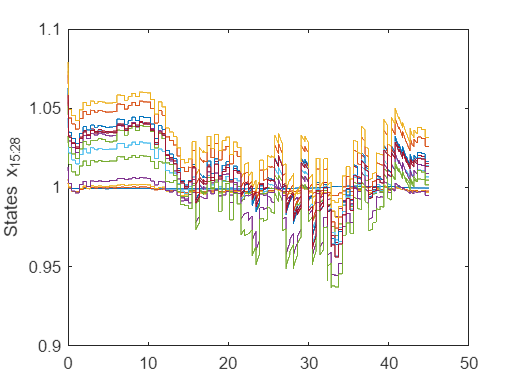

figure()
plot(t, VlinPlot+x);
ylabel("States x_{15:28}")
ylim([.9,1.1])

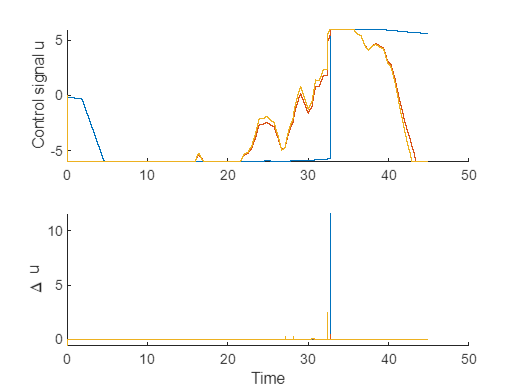


figure(1)
subplot(2,1,1)
hold on
stairs(t, u(1,:));
stairs(t, u(2,:));
stairs(t, u(3,:));
hold off
ylabel("Control signal u")
subplot(2,1,2)
hold on
stairs(t, du(1,:));
stairs(t, du(2,:));
stairs(t, du(3,:));
hold off
ylabel("\Delta u")
xlabel("Time")